This code computes the solution the the infinitesimal generator PDE

                      
$$$$\partial_t u + du(X) = - div_\mu(X) u $$
$$u(t^+, x) = \frac{1}{J_\mu^X(\Delta)u(t^-, x)}$$

$$


First we set the dimension and the bounds in each dimension

dims = 2;
%bounds = [-2 2; -2 2; -pi/3 pi/3];
bounds = [0 2;-2 2];
N = 50;

And we generate a uniform grid with $N$points in each dimension

grid = zeros(dims, N);
for i = 1:dims
    grid(i, :) = linspace(bounds(i, 1), bounds(i, 2), N);
end

Create a time array and set the integration step $\Delta t$

T = 10;
N_T = 20;
dt = T/N_T;

Initialize arrays to hold the solution $u\left(t,x\right)$ at each time step

if dims == 2
    u = zeros(N_T, N, N);
end
if dims == 3
    u = zeros(N_T, N, N, N);
end

Initialize the solution at time 0 with the initial density 

if dims == 3
for i = 1:N
    for j = 1:N
        for k = 1:N
            u(1, i, j, k) = initial_density([grid(1, i), ...
                grid(2, j), grid(3, k)]);
        end
    end
end
end
 if dims == 2
     for i = 1:N
         for j = 1:N
             u(1, i, j) = initial_density([grid(1, i), grid(2, j)]);
         end 
     end
 end



Suppose we have the values of $u$ up to $t$. And now we want to find them at a point $t+\Delta t$. For each element $x$ in the grid:

- Run the characteristics backward starting from $x$ back for $\Delta t$.

- Find the element on the grid closest to where the characteristic lands $x_{\textrm{grid}}$

- Update the value by the following rule if no impact happened

                   
$$$$u(t + \Delta t, x) = u(t, \varphi_{-\Delta t}^\mathcal{H}(x)) + \Delta t  c(\varphi_{-\Delta t}^\mathcal{H}(x),  u(t, \varphi_{-\Delta t}^\mathcal{H}(x))  )$$ $$ \approx u(t, x_{grid}) + \Delta t c(x_{grid}, u(t, x_{grid}))$$$$


        4. If an impact has happened multiply the result by the hybrid jacobian

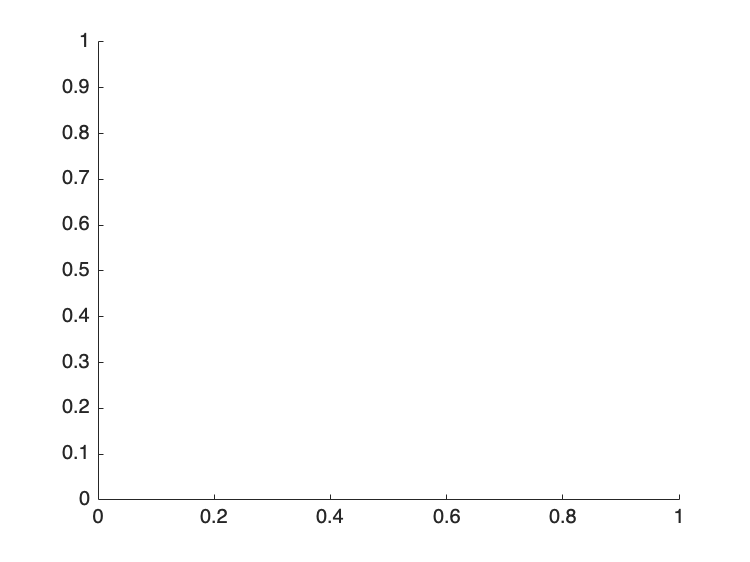

x_old =     2.0179   -1.5000


index_grid =     50     7


i = 29

x_old =     2.0587   -1.5000


index_grid =     50     7


i = 30

x_old =     2.0995   -1.5000


index_grid =     50     7


i = 31

x_old =     2.1403   -1.5000


index_grid =     50     7


i = 32

x_old =     2.1811   -1.5000


index_grid =     50     7


i = 33

x_old =     2.2219   -1.5000


index_grid =     50     7


i = 34

x_old =     2.2628   -1.5000


index_grid =     50     7


i = 35

x_old =     2.3036   -1.5000


index_grid =     50     7


i = 36

x_old =     2.3444   -1.5000


index_grid =     50     7


i = 37

x_old =     2.3852   -1.5000


index_grid =     50     7


i = 38

x_old =     2.4260   -1.5000


index_grid =     50     7


i = 39

x_old =     2.4668   -1.5000


index_grid =     50     7


i = 40

x_old =     2.5077   -1.5000


index_grid =     50     7


i = 41

x_old =     2.5485   -1.5000


index_grid =     50     7


i = 42

x_old =     2.5893   -1.5000


index_grid =     50     7


i = 43

x_old =     2.6301   -1.5000


index_grid =     50     7


i = 44

x_old =     2.6709   -1.5000


index_grid =     50     7


i = 45

x_old =     2.7117   -1.5000


index_grid =     50     7


i = 46

x_old =     2.7526   -1.5000


index_grid =     50     7


i = 47

x_old =     2.7934   -1.5000


index_grid =     50     7


i = 48

x_old =     2.8342   -1.5000


index_grid =     50     7


i = 49

x_old =     2.8750   -1.5000


index_grid =     50     7


i = 50

 if dims == 3
 for t = 2:N_T
     t
     for i = 1:N
         i
         for j = 1:N
             for k  = 1:N
                x_now = [grid(1, i), grid(2, j), grid(3, k)];
                [x_old, is_impact]  = run_backward...
                    (x_now, dt, @ reset_map, @impact, @eom);
                [x_prev, index_grid] = closest_grid_point...
                    (x_old, {N, bounds});
                u_prev = u(t - 1,index_grid(1), ...
                        index_grid(2), index_grid(3));
                if is_impact == 0
                    u(t, i, j, k) = u_prev + dt*div_X...
                        (x_prev, u_prev);
                end
                if is_impact == 1
                    u_prev = u_prev * hybrid_jacobian(x_prev);
                    u(t, i, j, k) = u_prev + dt*div_X...
                        (x_prev, u_prev);
                end
             end
         end
     end
 end
 end

 if dims == 2
     for t = 2:2
          for i = 1:N
             for j = 1:N
                  x_now = [grid(1, i), grid(2, j)];
                  [x_old, is_impact]  = run_backward...
                    (x_now, dt, @ reset_map, @impact, @eom);
                  [x_prev, index_grid] = closest_grid_point...
                    (x_old, {N, bounds});
                  u_prev = u(t - 1,index_grid(1), ...
                        index_grid(2));
                if is_impact == 0
                    u(t, i, j) = u_prev + dt*div_X...
                        (x_prev, u_prev);
                end
                if is_impact == 1
                    u_prev = u_prev * hybrid_jacobian(x_prev);
                    u(t, i, j) = u_prev + dt*div_X...
                        (x_prev, u_prev);
                end
                if j == 1 && i > 28 
                    x_old, index_grid, i
                end
             end
          end
     end
    
 end

In this section we run a bunch of tests:

- compute initial density at specific points

initial_density([2.0000, -1.5102])

ans = 0.0376

- run a trajectory backward for some time

hold off
ICs = [1.5 -2]

ICs =     1.5000   -2.0000


opt = odeset('Events', @impact, 'OutputFcn',@odephas2)%, 'OutputSel', 1);

opt = struct with fields:
              AbsTol: []
                 BDF: []
              Events: @impact
         InitialStep: []
            Jacobian: []
           JConstant: []
            JPattern: []
                Mass: []
        MassSingular: []
            MaxOrder: []
             MaxStep: []
         NonNegative: []
         NormControl: []
           OutputFcn: @odephas2
           OutputSel: []
              Refine: []
              RelTol: []
               Stats: []
          Vectorized: []
    MStateDependence: []
           MvPattern: []
        InitialSlope: []


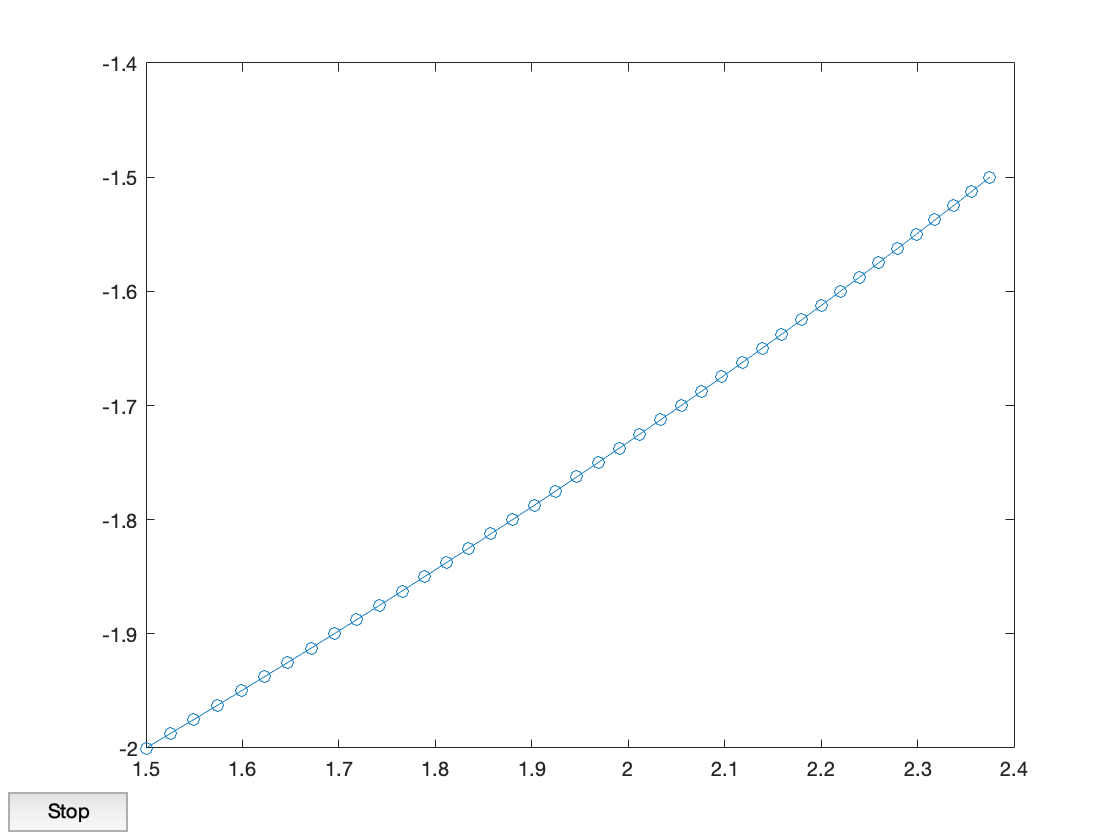

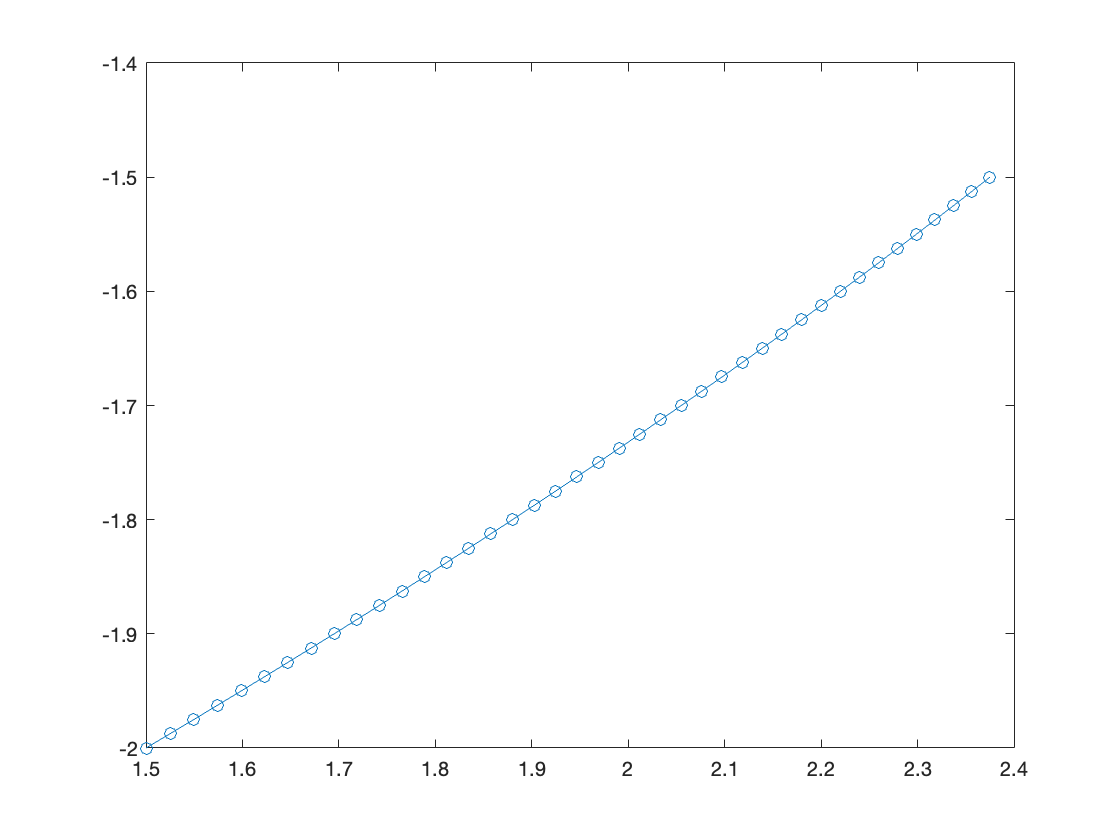

[t, y] = ode45(@eom, [dt, 0], ICs, opt);           


% apply the reset map
ICs = y(end, :);
t = t(end);
ICs = reset_map(ICs);
while t > 0
    [t, y] = ode45(eom, [t, 0], ICs, opts);
    ICs = y(end, :);            
    t = t(end);
    ICs = reset_map(ICs);   
    hold on;
end
x = y(end, :);

Plot the result

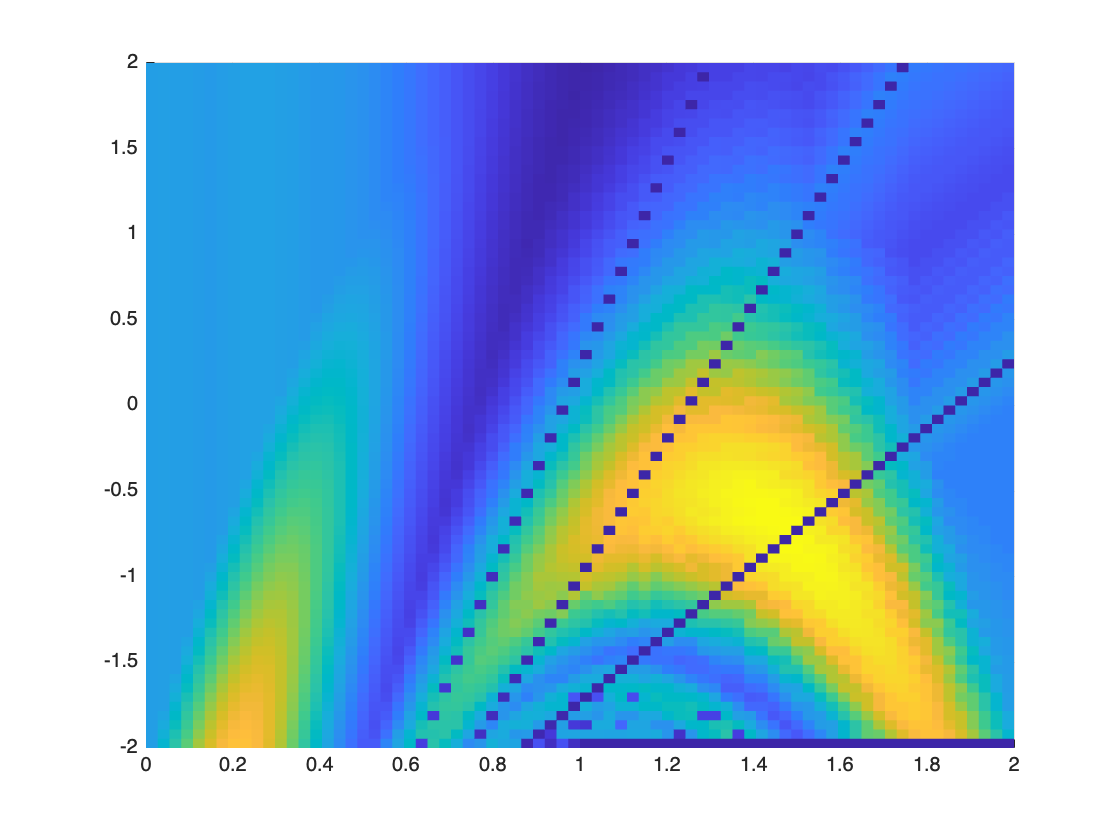

if dims == 2
    figure
    [X, Y] = meshgrid(grid(1, :), grid(2, :));
    for t = 1:N_T
        surf(X, Y, reshape(u(t, :, :),N, N), 'EdgeColor','none');
        axis([0 2 -2 2]);
        view([0, 90]);
        hold off

        pause(.1)
    end
end

 
 if dims == 3
    figure
    [X, Y] = meshgrid(grid(1, :), grid(2, :));
    for t = 1:N_T
        surf(X, Y, reshape(u(t, :, :, 25),N, N));
        axis([-2 2 -2 2 0 0.6]);
        view([0, 90]);
        hold off

        pause(.1)
    end
end

Here we define all the functions we need:

- the equations of motion

function dydx = eom(t, y)
    dydx = zeros(size(y));
    %% bouncing ball equations
     m = 1; g = 1;
     dydx(1) = y(2)/m;
     dydx(2) = -m*g;

    %% chaplygin sleigh equations
    % m = 1; I = 1; a = 1;
    % dydx(1) = a*y(2)^2;
    % dydx(2) = - (m*a)/(I + m*a^2)*y(1)*y(2);
    % dydx(3) = y(2);

    %% SIR model equations
    % b = 1, g = 1, d = 1, mu = 1;
    % dydx(1) =  - b*y(1)*y(2)/(y(1) + y(2) + y(3)) + ...
    %   mu(y(2) + y(3))
    % dydx(2) = b*y(1)*y(2)/(y(1) + y(2) + y(3)) - ...
    %   (g + mu + d) * y(2);
    % dydx(3) = g*y(2) - mu*y(3);

end

- the impact map

function [position,isterminal,direction] = impact(t, y)
    %% bouncing ball
     position = y(1);
     isterminal = 1;
     direction = -1;

    %% chaplygin sleigh
    %theta_0 = pi/3;
    %position = (y(3) - theta_0) *(y(3) + theta_0); 
    %isterminal = 1;  
    %direction = 1;

    %% SIR 
    % I0 = 3
    % position = y(2) - I0;
    % isterminal = 1;
    % direction = -1;
end

- the reset map

function y_plus = reset_map(y)
    y_plus = zeros(size(y));

    %% bouncing ball
     y_plus(1) = y(1);
     y_plus(2) = -y(2);

    %% chaplygin sleigh
     %y_plus(1) = y(1);
    % y_plus(2) = -y(2);
     %y_plus(3) = y(3);

    %% SIR
    % f = 0.3;
    % y_plus(1) = y(1);
    % y_plus(2) = (1 - f)*y(2);
    % y_plus(3) = y(3) + f*y(2);
end

- initial density

function rho = initial_density(x)
    % bouncing ball
     rho = exp(-(x(1) - 1)^2 - (x(2))^2);

    % chaplygin sleigh
    %rho =  exp(-sum(x.^2));

    % SIR
    % rho = exp(-sum(x.^2));
end

- divergence function 

function div = div_X(y, u)
    % bouncing ball 
     div = 0;

    % chaplygin sleigh
   % m = 1; a = 1; I = 1;
   % div = - m*a/(I + m*a^2)*y(1)*u;

    % SIR 
    % b = 1; g = 1; d = 1; mu = 1;
    % div = 3*mu + g + d + b*(y(2) - y(1)/(y(1) + y(2) + y(3))
end

- a function which determines which grid point is closest to the place where the characteristics intersect the time slice $t-\Delta t$. The information about the grid is passed in gird_info = [N, bounds] a list consisting of a real natural number and a matrix.

function [x_grid, i_grid] = closest_grid_point(x, grid_info)
    % extract information about the grid
    N = grid_info{1};
    bounds = grid_info{2};

    % initialize the point
    x_grid = zeros(size(x));
    i_grid = zeros(size(x));

    % find dimension of input
    dims = size(x);
    dims = dims(2);

    for i = 1:dims
        j = round((x(i) - bounds(i, 1))/(bounds(i, 2) ...
            - bounds(i,1))*(N - 1));
        % check if out of bounds
        if j > N - 1
            j = N - 1;
        end
        if j < 0
            j = 0;
        end
         
        x_grid(i) = bounds(i, 1) + j * (bounds(i, 2) ...
            - bounds(i ,1))/(N - 1);
        i_grid(i) = j + 1;
    end
end


- function that runs the characteristic backward for $\Delta \;t$ and returns the value at $t$ and whether an impact occured:

function [x, impact] = run_backward(x_now, dt, reset_map,...
    impact, eom)
    opts = odeset('Events', impact);
    impact = 0;
    [t, y] = ode45(eom, [dt, 0], x_now, opts);           

    % apply the reset map
    IC = y(end, :);
    t = t(end);
    IC = reset_map(IC);
    % keep integrating until another impact happens and repeat
    % procedure
    while t > 0
        [t, y] = ode45(eom, [t, 0], IC, opts);
        IC = y(end, :);            
        t = t(end);
        IC = reset_map(IC);    
        impact = 1;
        hold on;
    end
    x = y(end, :);
end


- hybrid jacobian function

function hj = hybrid_jacobian(x)
    % bouncing ball, chapplygin sleigh
    hj = 1;

    % SIR
    % f = 0.3;
    % hj = 1 - f;

end